# Open Climate Science in the [ENES](https://enesdataspace.vm.fedcloud.eu/access.html) Data Space Portal

Author: Kostas Leptokaropoulos and Shubo Chakrabarti

Copyright 2024, The MathWorks, Inc.

## Introduction

**Public Data: **Many public databases have been created for the purposes of making data freely accessible to the scientific community. A best practice is to assign a unique identifier to a dataset, so that it is discoverable. A common form of a unique identifier is a [Digital Object Identifier or DOI](https://en.wikipedia.org/wiki/Digital_object_identifier)® which points to the data. 

**Access Public Data:** To access and process public data, you can use several routes. 

- Download data files to your local machine and work with them in MATLAB®. 

- Access data directly via an API. MATLAB's function that [import data from NetCDF files](https://www.mathworks.com/help/matlab/network-common-data-form.html) from RESTful API used by many portals.

- If the portal offers only Python® bindings, [call Python from MATLAB](https://www.mathworks.com/help/matlab/call-python-libraries.html).

**Data formats:** MATLAB supports a wide range of data formats

- There are a wide range of scientific data formats that can be [natively read in MATLAB](https://www.mathworks.com/help/matlab/scientific-data.html). They include NetCDF, HDF5 and GRIB as well as more specialized data formats. 

- In addition, the [Mapping Toolbox](https://uk.mathworks.com/products/mapping.html) contains [built-in functions](https://www.mathworks.com/help/map/file-import-and-export.html) to read data from many online data repositories in standard geo-data formats.

- Sometimes data import functions may be [written by the Geoscience community](https://uk.mathworks.com/matlabcentral/fileexchange/?category%5B%5D=overview%2Fsciences1689.support%2Fearth-oce840&q=data+read), and published on the MATLAB [File Exchange](https://uk.mathworks.com/matlabcentral/fileexchange/?category%5B%5D=overview%2Fsciences1689.support%2Fearth-oce840) - a portal for community contributions in MATLAB. All community contributions are covered by open source licenses, which means they can be re-used, modified or added to. Exact terms and conditions depend on the licenses used by the author.

In this example, we will access global climate data from the [`ENES`](https://enesdataspace.vm.fedcloud.eu/access.html) Data Space Portal

## Data and Resources

Data from the WCRP CMIP6 (World Climate Research Programme Coupled Intercomparison Project - Phase 6, e.g.,

[https://esgf-data.dkrz.de/search/cmip6-dkrz/](https://esgf-data.dkrz.de/search/cmip6-dkrz/))

`These data are located within the `[`ENES`](https://enesdataspace.vm.fedcloud.eu/access.html)` Data Space Portal, so you can work online, and run the Jupyter Notebook or MATLAB Live Script from your personal workspace (in this case: `[https://enesdataspace.vm.fedcloud.eu/jupyter/hub/user-redirect/lab/tree/data](https://enesdataspace.vm.fedcloud.eu/jupyter/hub/user-redirect/lab/tree/data)`)`

[](https://enesdataspace.vm.fedcloud.eu/jupyter/hub/user-redirect/lab/tree/data)

## Import Data from the ENES Data Space

clearvars; clc; close all

You can read any 2 datasets, one imported as "URLpast" and one (any subsequent set can be selected), as "URLproj"

% read data files from the ENES database 
 URLpast = "/home/jovyan/data/CMIP6/HighResMIP/CMCC/CMCC-CM2-VHR4/highresSST-present/r1i1p1f1/day/pr/gn/v20210308/pr_day_CMCC-CM2-VHR4_highresSST-present_r1i1p1f1_gn_19560101-19561231.nc"
 URLproj = "/home/jovyan/data/CMIP6/HighResMIP/CMCC/CMCC-CM2-VHR4/highresSST-future/r1i1p1f1/day/pr/gn/v20210308/pr_day_CMCC-CM2-VHR4_highresSST-future_r1i1p1f1_gn_20330101-20331231.nc";
ncdisp(URLpast)
ncdisp(URLproj)


Read the precipitation flux as "Variable"


Variable = "pr";
A = ncinfo(URLpast)  % select between URLpast and URLproj

## Read Geospatial Data


lon = double(ncread(URLpast,'lon'));
lat = double(ncread(URLpast,'lat'));


executing the following line either returns an error, or causes delay. This is because data is too big and should be first filtered! Please comment next line and run the section again.

% Var = double(ncread(URLpast,Variable));

#### Filter Data in Time and Space

Select boundaries of a rectangual area

%minimum and maximum longitude
minlon = 15;maxlon = 35; % from 0 to 360
%minimum and maximum latitude
minlat = 35;maxlat = 50; % from -90 to 90

Select first day and number of days after the first 

starttime = 100;counttime = 190;% from 1 to 365

indlon = find(lon>=minlon & lon<=maxlon); 
indlat = find(lat>=minlat & lat<=maxlat); 

startlon=indlon(1);countlon=numel(indlon); 
startlat=indlat(1);countlat=numel(indlat); 


## Import Filtered Data

lat = double(ncread(URLpast,'lat',startlat,countlat));
lon = double(ncread(URLpast,'lon',startlon,countlon));
tpast = double(ncread(URLpast,'time',starttime,counttime));
tproj = double(ncread(URLproj,'time',starttime,counttime));
Varpast = double(ncread(URLpast,Variable,[startlon startlat starttime],[countlon countlat counttime]));
Varproj = double(ncread(URLproj,Variable,[startlon startlat starttime],[countlon countlat counttime]));
unit = ncreadatt(URLpast,'pr','units') % this will change in the next lines


### Convert units from sec-1 to day-1

already for this dataset

 Varpast = Varpast*86400;
 Varproj = Varproj*86400;
 newunit = "kg m^-^2 day^-^1"

### Calculate times

Beware of the starting dates of the two datasets ("*past"* and "*pro*j")!! Take a look at the "time units" in the corresponding NetCDF files.

Tpast = datetime('1950-1-1')+tpast + 2,Tproj = datetime('2015-1-1')+tproj + 5

***** **You will also need to add in the "Tpast" and "Tproj" the number of leap years from [https://miniwebtool.com/leap-years-list/?start_year=1950&end_year=2013](https://miniwebtool.com/leap-years-list/?start_year=1950&end_year=2013) 

You can use the 'leapyear' function if the 'aerospace toolbox' is installed [e.g. Tpast = datetime('1950-1-1')+tpast+sum(leapyear(1950:1953))]


Tpast.Format = 'dd-MMM-uuuu';Tproj.Format = 'dd-MMM-uuuu';
Tpast_str = string(Tpast);
Tproj_str = string(Tproj);


## Select a day to plot precipitation data

close all
%Select a day

t1 = Tpast_str(12);inx = Tpast_str == t1;

[lat1,lon1] = meshgrid(lat,lon);
Var1past = Varpast(:,:,inx);
Var1proj = Varproj(:,:,inx);
mV = min([min(Var1past(:)),min(Var1proj(:))])
MV = max([max(Var1past(:)),max(Var1proj(:))])


Customize Colormap limits to the selected data


  CBmin = 0;
  CBmax = 63.3048165589571;

## Visualize and compare past and projected data


tiledlayout(1,2)
nexttile % past map
worldmap([minlat maxlat],[minlon maxlon])
geoshow(lat1,lon1,Var1past,'DisplayType','texturemap','FaceAlpha',0.5);
geoshow('landareas.shp','EdgeColor','black','FaceColor','none')
title([ncreadatt(URLpast,Variable,'long_name'),'on',t1])
  clim([CBmin CBmax])

nexttile %projection map
worldmap([minlat maxlat],[minlon maxlon])
geoshow(lat1,lon1,Var1proj,'DisplayType','texturemap','FaceAlpha',0.5);
geoshow('landareas.shp','EdgeColor','black','FaceColor','none')
 cb = colorbar; % display colorbar
 cb.Location='eastoutside';
 cb.Label.String = (newunit);
title([ncreadatt(URLproj,Variable,'long_name'),'on',Tproj_str(inx)])
  clim([CBmin CBmax])

 colormap turbo

## Some Stats!

### Compare incremental and cumulative precipitation

figure
N = numel(tpast)

Select number of days (between 1 and N)

T1 = Tpast_str(1);inx1 = Tpast_str == T1;n1 = find(inx1);
T2 = Tpast_str(190);inx2 = Tpast_str == T2;n2 = find(inx2);
n = n2 - n1 +1;
if n2<=n1;error('End date (n2) should be greater than start date (n1)');end


### Generate Box Charts

Boxp1 = zeros(size(n,1));Boxp2 = zeros(size(n,1));cou=1;
for i=n1:n2
Boxp1(cou) = sum(Varpast(:,:,i),"all");
Boxp2(cou) = sum(Varproj(:,:,i),"all");
cou=cou+1;
end

% Daily plots
figure
plot(Tpast(n1:n2),Boxp1,'r-',Tpast(n1:n2),Boxp2,'k-',LineWidth=1);datetick('x',6);ylabel('daily sum');xlabel('date');
hold on
yyaxis right;plot(Tpast(n1:n2),cumsum(Boxp1),'r--',Tpast(n1:n2),cumsum(Boxp2),'k--');datetick('x',6);ylabel('cummulative');xlabel('date');
legend(num2str(year(Tpast(1))),num2str(year(Tproj(1))),num2str(year(Tpast(1))),num2str(year(Tproj(1))))

% Box charts
figure
group = categorical([repmat("past", size(Boxp1));repmat("projection", size(Boxp2))]);
boxchart([Boxp1',Boxp2']);xticklabels({'past','projection'});
title(["Daily Sum Average","past/projection ratio = "+num2str(sum(Boxp1)/sum(Boxp2),'%7.1f')])


### Perform 3 Statistical Tests to evaluate the significance of the results

%Stats
[p.Wilcoxon,h.Wilcoxon] = ranksum(Boxp1,Boxp2); % null hypothesis, h0, equal medians
[h.ttest2,p.ttest2] = ttest2(Boxp1,Boxp2); % null hypothesis, h0, equal means
[h.kstest2,p.kstest2] = kstest2(Boxp1,Boxp2); % null hypothesis, h0, samples from same distibution
h.ttest2 = logical(h.ttest2);

if h.Wilcoxon==0;disp(['>> The Wilcoxon rank sum test FAILS to reject the hypothesis of equal medians at ' ,num2str(p.Wilcoxon) ' significance'])
else; disp(['>> The Wilcoxon rank sum test REJECTS the hypothesis of equal medians at ',num2str(p.Wilcoxon), ' significance'])
end

if h.ttest2==0;disp(['>> The 2-sample t-test FAILS to reject the hypothesis of equal means at ' ,num2str(p.ttest2) ' significance'])
else; disp(['>> The 2-sample t-test REJECTS the hypothesis of equal means at ',num2str(p.ttest2), ' significance'])
end

if h.kstest2==0;disp(['>> The 2-sample Kolmogorov-Smirnov test FAILS to reject the hypothesis that the two samples come from the same distribution at ' ,num2str(p.kstest2) ' significance'])
else; disp(['>> The 2-sample Kolmogorov-Smirnov test REJECTS the hypothesis that the two samples come from the same continuous distribution at ',num2str(p.kstest2), ' significance'])
end
   disp('- - - - - - - - - - - - - - - - - - - - - - - - - - - - - - - - - - - - - - - - - - - - - - - - - - - - - - - - - - - - - - - - - - - - - - - -')


## Export and Share

If you have version R2023b or later, you can use the [export](https://de.mathworks.com/help/matlab/ref/export.html) function to export the Live Script as *Jupyter Notebook**, *by typing:

% export("Analyzing_Global_Precipitation_Data.mlx","Analyzing_Global_Precipitation_Data.ipynb")

----------------------------------------------------------------------------------------

Go to LIVE EDITOR menu, Click "Export" and select Export format.

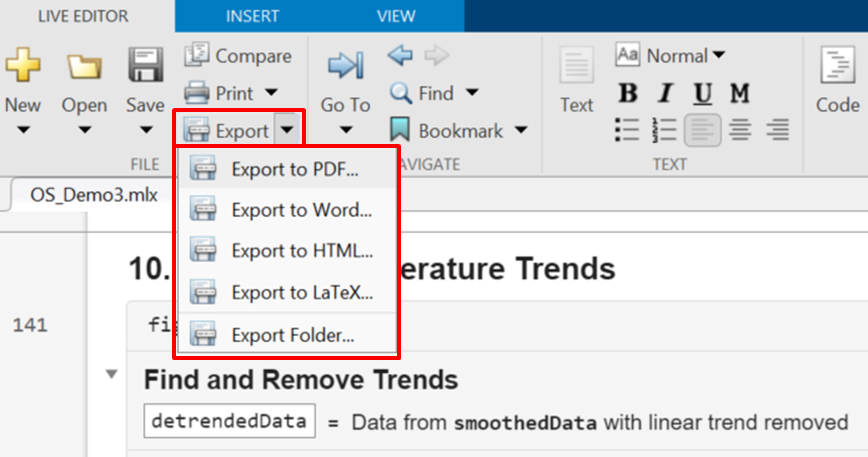

## Publish reusable MATLAB code for reproducible results

To enable collaboration partners, reviewers and the community reuse your MATLAB code and reproduce your results.

- Publish your MATLAB code (eg: on GitHub) and generate a [DOI](https://en.wikipedia.org/wiki/Digital_object_identifier) (digital object identifier) by [linking it to a DOI generating portal](https://docs.github.com/en/repositories/archiving-a-github-repository/referencing-and-citing-content)(egs. [Figshare](https://help.figshare.com/article/how-to-connect-figshare-with-your-github-account#:~:text=You%20can%20get%20set%20up,where%20you'll%20authorise%20figshare.)®, [Zenodo](https://docs.github.com/en/repositories/archiving-a-github-repository/referencing-and-citing-content)®). Make your research output findable by including as much information as needed in the metadata. Document your code well explaining steps required to reproduce clearly and explicitly.

- Make sure you include a license for your code that specifies reuse and re-distribution rights for the code. Various open source licenses are [available](https://opensource.org/licenses/). BSD, MIT and Apache licenses are commonly used for open research software.

- [Link your GitHub repository to File Exchange](https://www.mathworks.com/matlabcentral/content/fx/about.html?s_tid=gn_mlc_fx_help#Why_GitHub) to make your MATLAB code available to MATLAB users via the Add-Ons button. 

            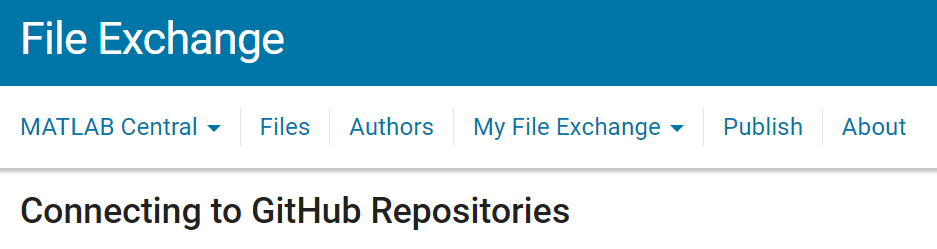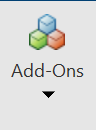

- Make your MATLAB code **interoperable**. MATLAB is [interoperable](https://www.mathworks.com/products/matlab/matlab-and-other-programming-languages.html) with several other languages including C, Fortran and Python. MATLAB can be directly called from Python using the [MATLAB Engine for Python](https://www.mathworks.com/help/matlab/matlab-engine-for-python.html)® which is available as a PyPI® package and can be installed using the command `pip install matlab.engine` from Python. MATLAB code can also be [packaged as a Python library](https://www.mathworks.com/help/compiler_sdk/gs/create-a-python-application-with-matlab-code.html) and called from Python. Deep Learning models from other frameworks are [interoperable with MATLAB](https://www.mathworks.com/help/deeplearning/ug/interoperability-between-deep-learning-toolbox-tensorflow-pytorch-and-onnx.html) either using the [ONNX™ interface](https://www.mathworks.com/matlabcentral/fileexchange/67296-deep-learning-toolbox-converter-for-onnx-model-format) or via direct interfaces that exist, for example, for Pytorch® and Tensorflow™ models. 

          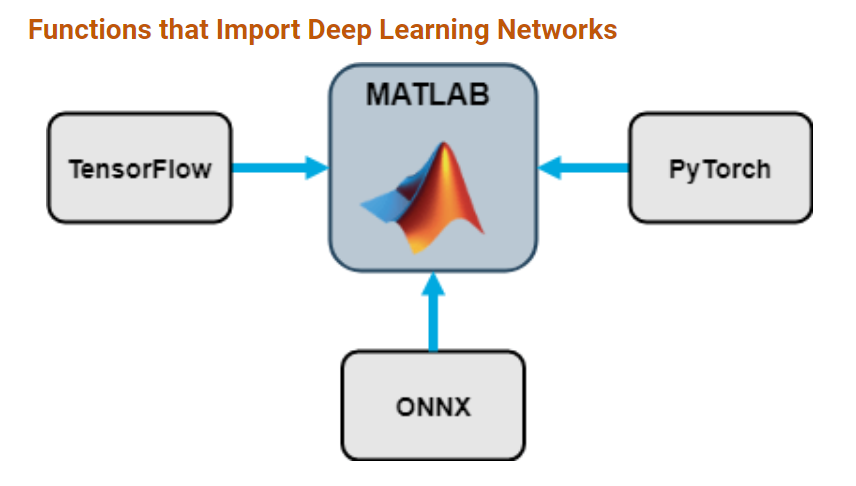

- MATLAB is interoperable with cloud architectures such as [JupyterHub](https://www.mathworks.com/products/reference-architectures/jupyter.html)® and MATLAB code can also be used within Jupyter Notebooks. Here is a link to a Jupyter® notebook of the same example used here. There is an official MATLAB kernel for Jupyter Notebooks - read about it [here](https://blogs.mathworks.com/matlab/2023/01/30/official-mathworks-matlab-kernel-for-jupyter-released/). To easily convert a Live Script into a Jupyter Notebook use the `export` function.

          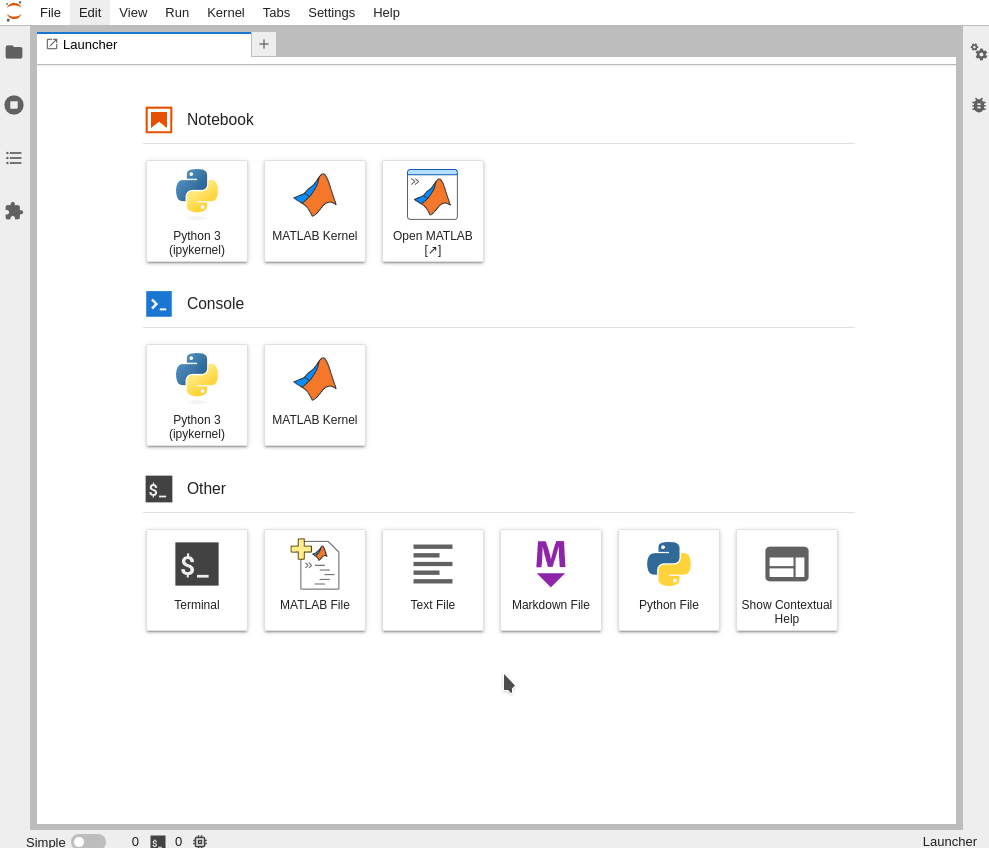

- Run your [MATLAB code on the browser directly from GitHub](https://www.mathworks.com/help/matlab/matlab_env/open-github-repositories-in-matlab-online.html). Copy and paste the GitHub repo address into [this app](https://www.mathworks.com/products/matlab-online/git.html). That will generate a command, which when pasted into your README, will create a "Open in MATLAB Online™" button on your GitHub repository. By clicking on this button, users will be able to run your code in the browser on MATLAB Online.

           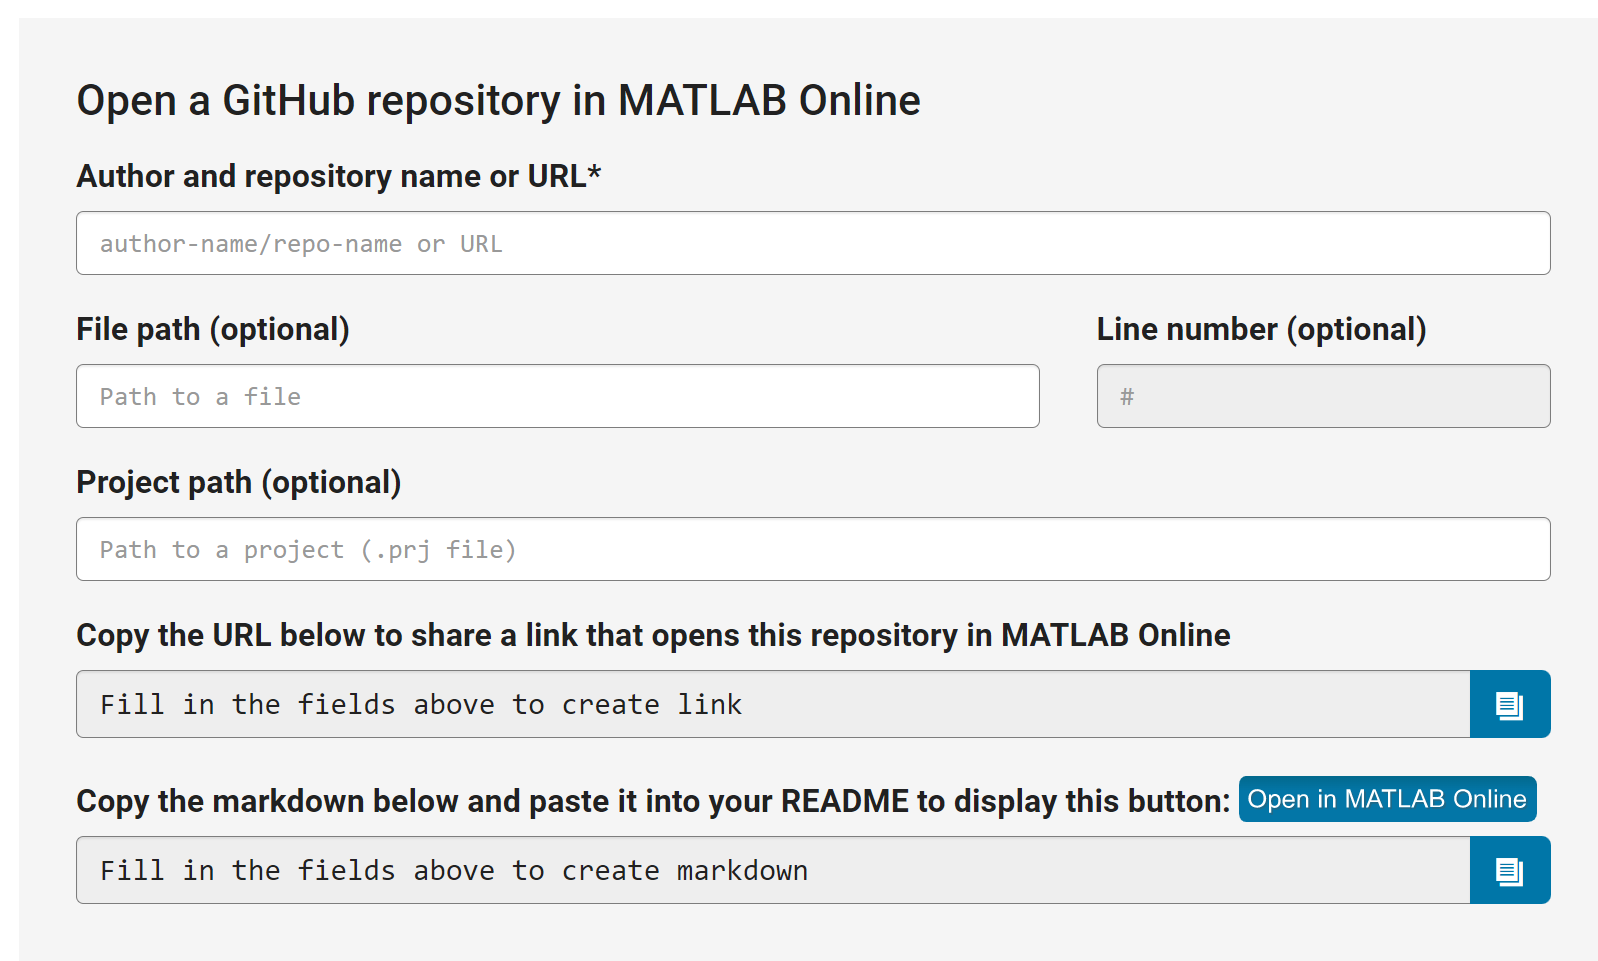

- Make your MATLAB code reproducible by using a reproducibility portals that supports MATLAB. One example is Code Ocean®. On Code Ocean, you can [upload your MATLAB code](https://help.codeocean.com/en/articles/1120384-which-toolboxes-are-included-with-matlab) including dependencies. Once uploaded, your code is tested and published as a Code Ocean "capsule" which can be run online or downloaded and run locally by users. Code Ocean also generates a DOI for your code capsule.  For Live Scripts, convert the `.mlx` file into a `.m` file and a `.html` file using the [`export`](https://de.mathworks.com/help/matlab/ref/export.html) function for best results. Here is the DOI for the Code Ocean capsule of the this code. Read more about MATLAB on Code Ocean [here](https://blogs.mathworks.com/loren/2021/07/15/sharing-and-running-matlab-code-in-the-cloud/#H_795BB86B).

         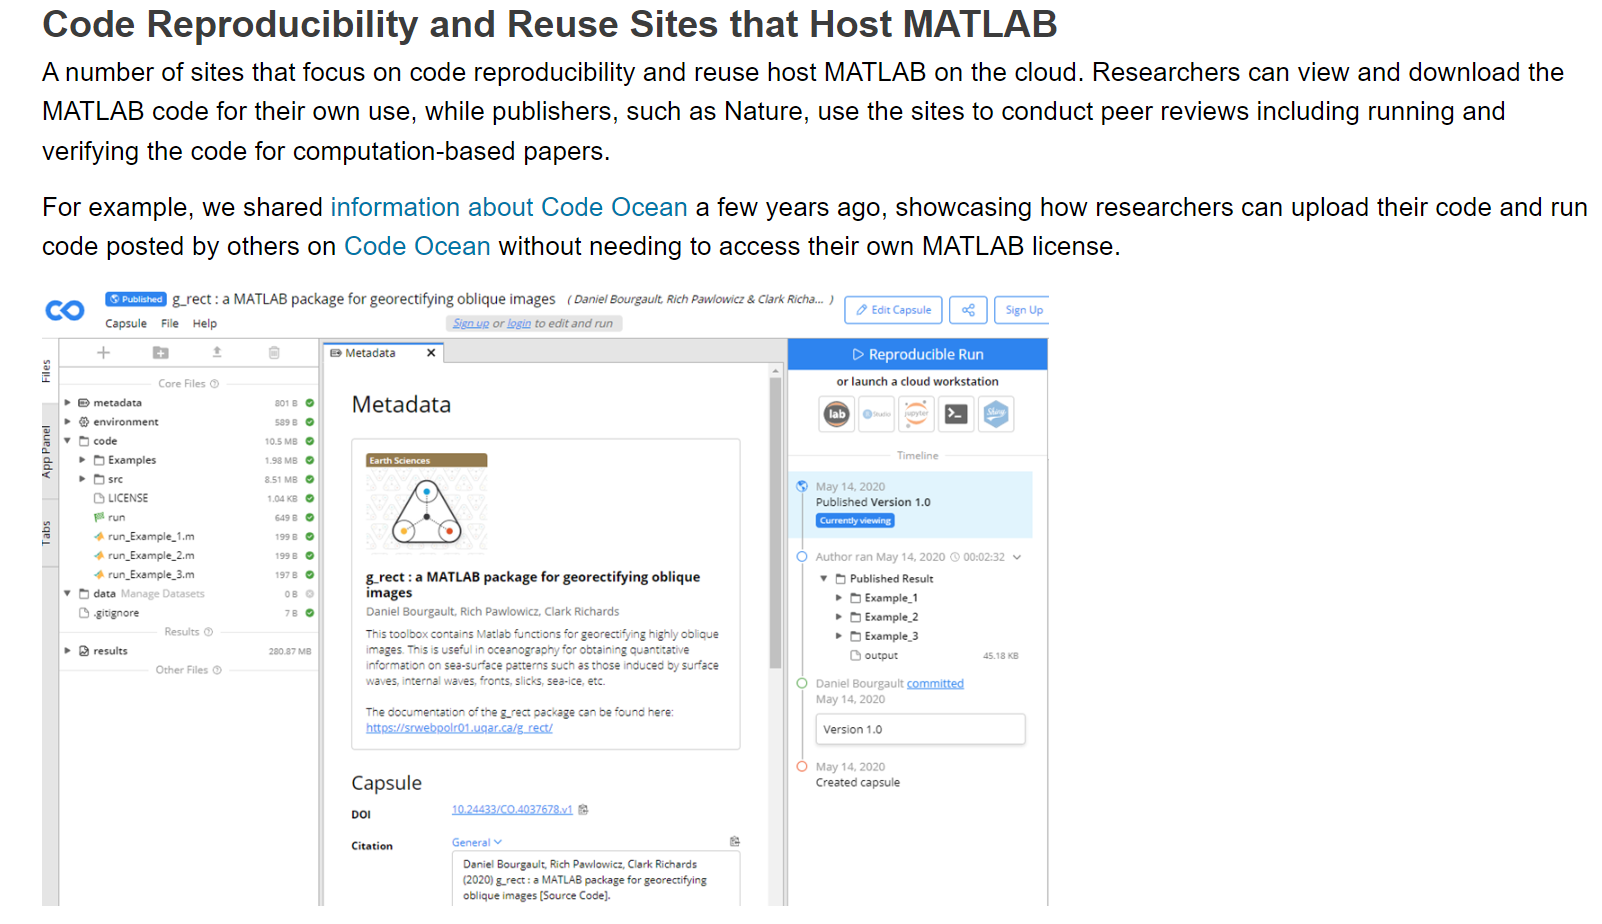

- **Warning**: Before making your code available on the cloud, make sure all dependencies including any data that is needed for your code to run is uploaded along with the code. Also make sure any path and/or filenames that refer to local directories are appropriately renamed.

- FAIR standards: FAIR is an acronym that stands for **F**indable, **A**ccessible, **I**nteroperable and **R**eproducible. It is an [accepted standard](https://www.nature.com/articles/s41597-022-01710-x) for research output (code, data) and is often required for your research results to be in [compliance with "Open Science" standards](https://research-and-innovation.ec.europa.eu/strategy/strategy-2020-2024/our-digital-future/open-science_en). Adhering to the above pointers helps in making your MATLAB code FAIR